# 2DOF PID y MHPID lineal

## PID

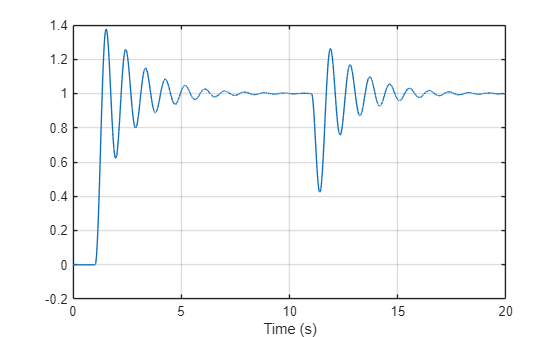

t = pid2.Time;
y = pid2.Data; 

ti = 29; % tiempo de inicio
idx = find(t >= ti, 1, 'first'); 
t2 = t(idx:end) - t(idx);
y2 = y(idx:end, :);

plot(t2, y2);
xlabel('Time (s)');
%ylabel('Signal');

xlim([0 20])
grid on;
hold on

## MHPID-FLC

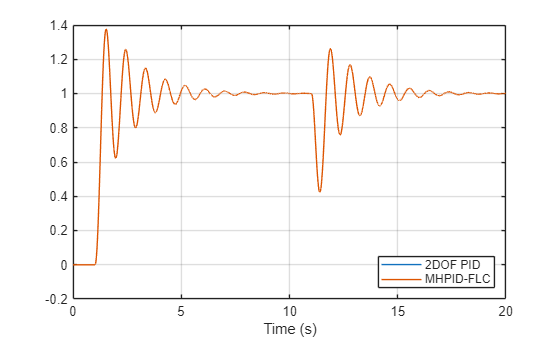

t = mhpid.Time;           % vector tiempo
y = mhpid.Data; % matriz señal (NxM)

% Si guardó como timeseries:
% t = ts.Time;
% y = ts.Data;

idx = find(t >= ti, 1, 'first'); % primer índice >= ti
t2 = t(idx:end) - t(idx);        % desplazar para que ti sea 0
y2 = y(idx:end, :);              % datos desde ti hasta el final

plot(t2, y2);

%ylim([-2 4])
legend('2DOF PID', 'MHPID-FLC', 'Location', 'southeast')